
%Generate random signal
t = (0:0.001:1)';
S1 = 2*randn(size(t));
%Trunk 50 samples  
S1 = S1(1:50);
%Create delayed signal
S2 = S1; 
S2 = [zeros(10,1); S2(1:40)]; %Add zeros at the beginning
subplot(3,1,1)
plot(1:50,S1)
%subplot(3,1,2)
%plot(1:50,S2)
hold

Current plot held



%Calculate cross-correlation
[r1,n] = xcorr(S1,S2);
subplot(3,1,3)
plot(n,r1)
%And delay
[m,p] = max(r1)

m = 133.0145

p = 40

delay = n(1,p)

delay = -10


%Atenuate S2 and add noise
S2 = S2*0.5;
S2 = S2 + 0.5*randn(size(S2));
%hold
subplot(3,1,2)
plot(1:50,S2)
%Recalculate cross-correlation and compare
[r1,n] = xcorr(S1,S2);
%r1 = r1/abs(max(r1))

r1 =     0.0018
    0.0058
   -0.0113
   -0.0336
    0.0030
   -0.0091
    0.0719
    0.0405
   -0.0690
   -0.0684


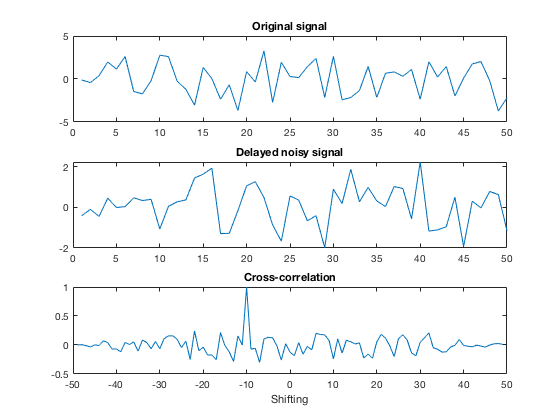

subplot(3,1,3)
plot(n,r1)

subplot(3,1,1)
title('Original signal')
subplot(3,1,2)
title('Delayed noisy signal')
subplot(3,1,3)
title('Cross-correlation')
xlabel('Shifting')